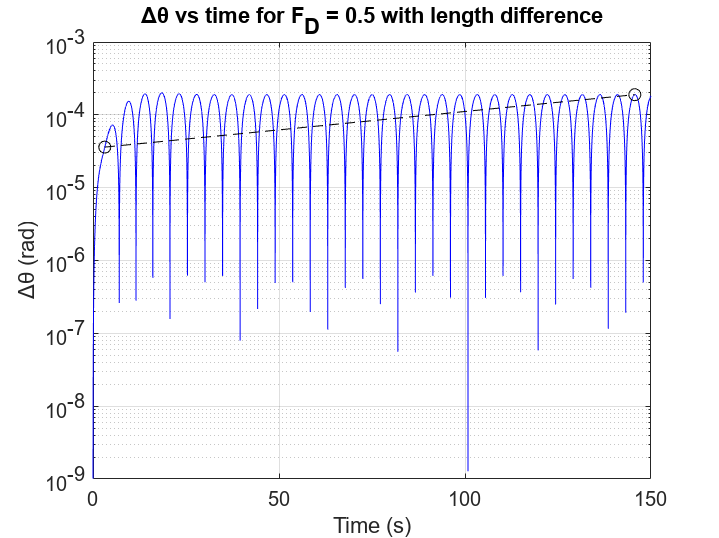

% Define the constants for the pendulum
g = 9.8;  % Acceleration due to gravity (m/s^2)
l = 9.8;  % Length of the pendulum (m)
delta_l = 0.001;  % Small difference in the length of the pendulum
q = 0.5;  % Damping coefficient
Omega_D = 2/3;  % Driving frequency
theta0 = 0.2;  % Initial angle (rad)
omega0 = 0;  % Initial angular velocity (rad/s)
t_max = 150;  % Max time for simulation
dt = 0.04;  % Time step size

% Define the pendulum equation with length as a parameter
pendulum_eq = @(t, y, Fd, l) [y(2); -(g/l)*sin(y(1)) - q*y(2) + Fd*sin(Omega_D*t)];

% Define options for ode solver to use a fixed time step
options = odeset('MaxStep', dt, 'InitialStep', dt, 'RelTol', 1e-5);

% Simulate for Fd = 0.5 with original length
[t1, y1] = ode45(@(t, y) pendulum_eq(t, y, 0.5, l), [0, t_max], [theta0, omega0], options);

% Simulate for Fd = 0.5 with modified length
[t1_prime, y1_prime] = ode45(@(t, y) pendulum_eq(t, y, 0.5, l + delta_l), [0, t_max], [theta0, omega0], options);

% Calculate Δθ for Fd = 0.5 with length difference
delta_theta1 = abs(wrapToPi(y1(:, 1)) - wrapToPi(y1_prime(:, 1)));

% Simulate for Fd = 1.2 with original length
[t2, y2] = ode45(@(t, y) pendulum_eq(t, y, 1.2, l), [0, t_max], [theta0, omega0], options);

% Simulate for Fd = 1.2 with modified length
[t2_prime, y2_prime] = ode45(@(t, y) pendulum_eq(t, y, 1.2, l + delta_l), [0, t_max], [theta0, omega0], options);

% Calculate Δθ for Fd = 1.2 with length difference
delta_theta2 = abs(wrapToPi(y2(:, 1)) - wrapToPi(y2_prime(:, 1)));

% Plotting Δθ vs time for Fd = 0.5
figure;
semilogy(t1, delta_theta1, 'b-');
title('Δθ vs time for F_D = 0.5 with length difference');
xlabel('Time (s)');
ylabel('Δθ (rad)');
grid on;
hold on;

y = [3.6032e-05 0.0001892];
x = [3.16 145.65];
plot(x,y,'ko--');
hold off;

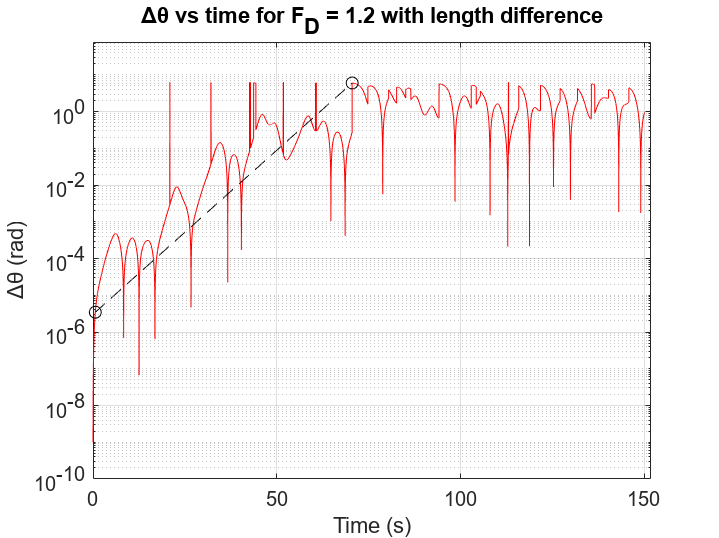


% Plotting Δθ vs time for Fd = 1.2
figure;
semilogy(t2, delta_theta2, 'r-');
title('Δθ vs time for F_D = 1.2 with length difference');
xlabel('Time (s)');
ylabel('Δθ (rad)');
grid on;
hold on;

y = [3.463e-06 6.01165];
x = [0.63 70.5];
plot(x,y,'ko--');
hold off;


% Display the figures
drawnow;